- Synapric inputs in a passive cable

(1) 

X = 'For inhibitory, the peak value is -17.585906 mV, the time of peak is at 1.809045 ms.'

Y = 'For excitatory, the peak value is 61.550670 mV, the time of peak is at 3.819095 ms.'

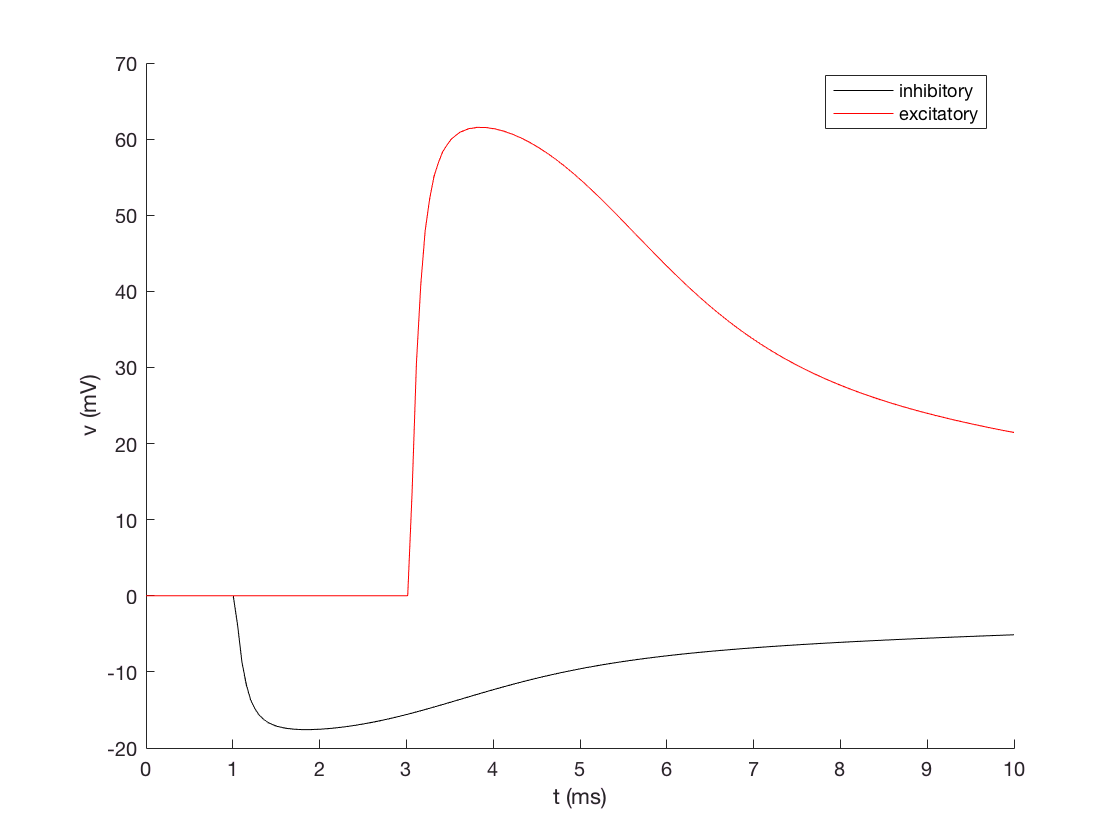

syn = struct('t1',1,'gsyn',1*1e-4,'loc',0.06,'vsyn',-20);
[~, v1_1] = mid1(syn);
syn = struct('t1',3,'gsyn',1*1e-4,'loc',0.04,'vsyn',70);
[t, v1_2] = mid1(syn);
v1(1,:) = v1_1;
v1(2,:) = v1_2;
prt(t,v1)

(2)

X = 'For inhibitory, the peak value is -17.585906 mV, the time of peak is at 3.819095 ms.'

Y = 'For excitatory, the peak value is 61.550670 mV, the time of peak is at 1.809045 ms.'

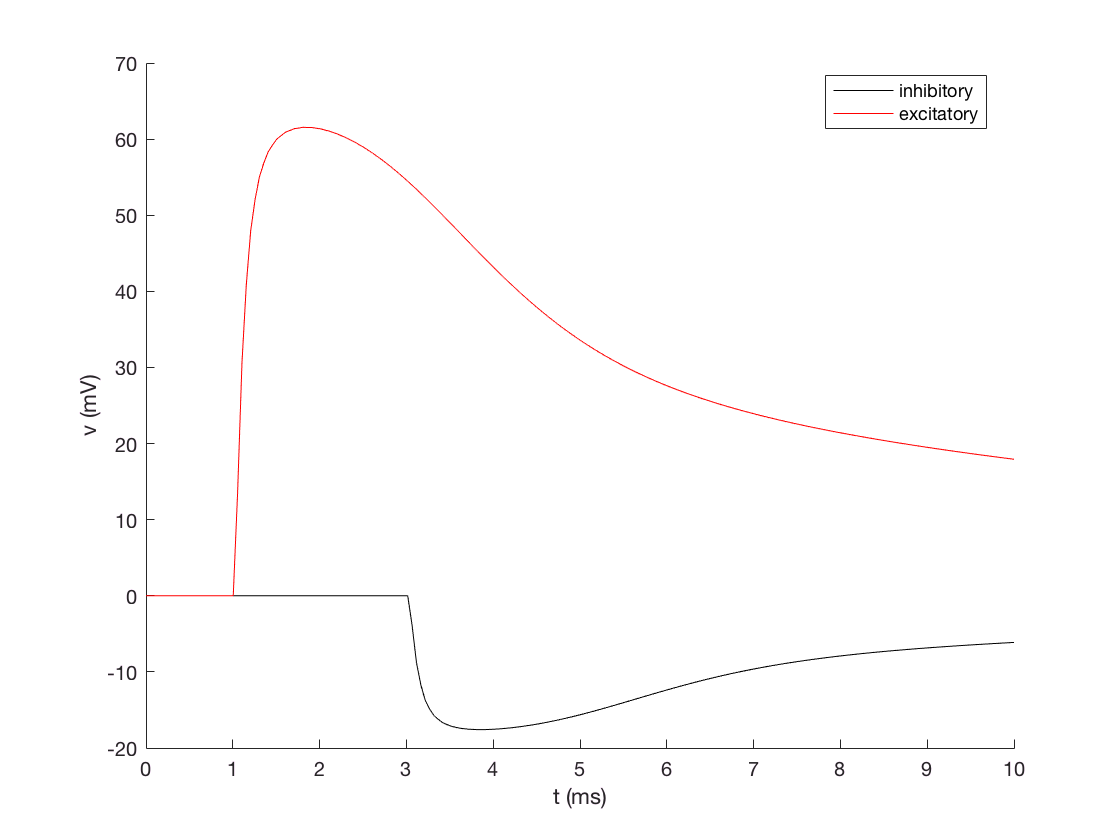

syn = struct('t1',3,'gsyn',1*1e-4,'loc',0.04,'vsyn',-20);
[~, v1_1] = mid1(syn);
syn = struct('t1',1,'gsyn',1*1e-4,'loc',0.06,'vsyn',70);
[t, v1_2] = mid1(syn);
v1(1,:) = v1_1;
v1(2,:) = v1_2;
prt(t,v1)

(3) The locations of synapses and the properties (either inhibitory or excitatory) are the factors that are likely responsible for the change in peak depolarization.

2. Theory and practice of Fourier transforms

(1) 

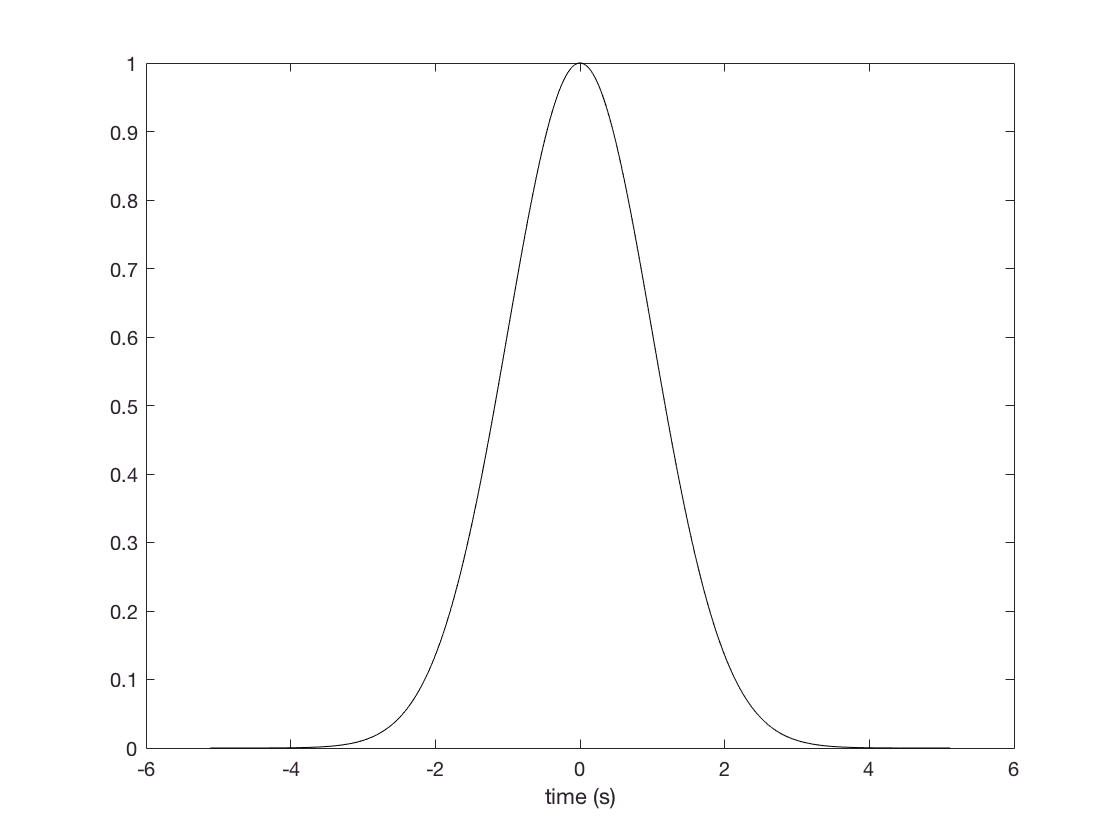

t = -5.11:0.01:5.12;
g = exp(-t.^2/2);
plot(t,g,'k')
xlabel('time (s)')

(2) The Nyquist frequency can be obtained by half of the sampling rates. The sampling rates above is $\frac{1024}{5.12-(-5.11)} \approx 100.1 $ Hz. Thus the Nyquist Frequency is ~ 50.5 Hz.

For $d\omega$, $d\omega = \frac{1}{T} = \frac{1}{5.12} \approx 0.195$ Hz 

(3)

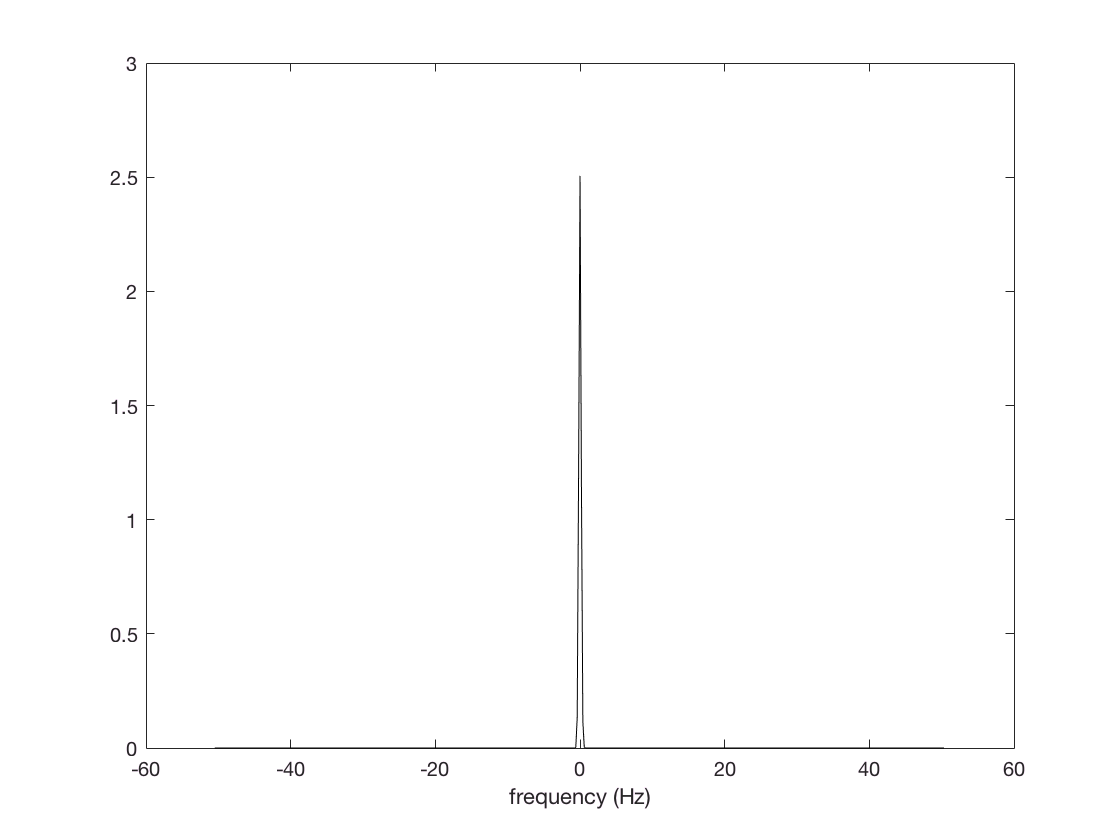

omega = -50.5:0.195:50.5;
g_hat_t = sqrt(2*pi)*exp(-(2*pi*omega).^2/2);
plot(omega,g_hat_t,'k')
xlabel('frequency (Hz)')

(4) First, MATLAB **fft** function will give numerical Fourier series of series $g(t)$. The result is $\frac{\hat{g}(\omega) }{dt}$. The Fourier series obtained by **fft** include both real part and imaginary part, while the theoretical formula of Fourier transform only gives real part. In addition, direct **fft **function will give frequency with the same sampling rate as original $g(t)$, while theoretical formular used Nyquist frequency. 

(5)

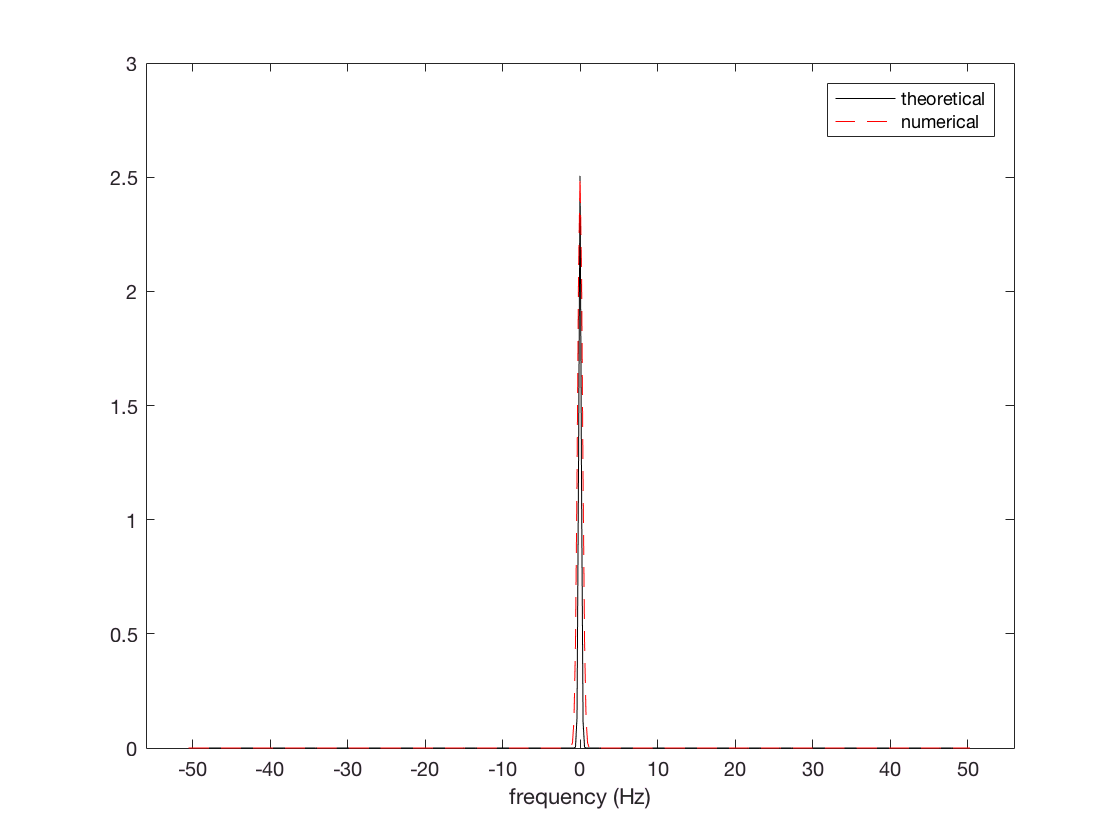

g_t(1:513) = g(512:1024);
g_t(514:1024) = g(1:511);
g_hat = fft(g_t)*0.01;
ghat(1:511) = g_hat(514:1024);
ghat(512:1024) = g_hat(1:513);
ghat = ghat;
sample = length(omega);
c = length(ghat);
start = c/2-sample/2;
g_hat_n = real(ghat(start:start+sample-1));
plot(omega,g_hat_t,'k', omega,g_hat_n,'r--')
xlabel('frequency (Hz)')
xlim([-56 56])
legend('theoretical', 'numerical')
ylim([0 3])

(6)

maxi = max(imag(ghat));
display(maxi)

maxi = 1.5841e-16

The maximal value of the imaginary part is $1.5841\times10^{-16}$ , which can be neglected.

For a Gaussian distribution, $\hat{g}(\omega) = \eta(\omega)e^{2\pi i\psi(\omega)}$, with modulus $\eta(\omega)\geq 0$ and phase $\psi(\omega)$. First, because $g(x)$ is real, $\hat{g}(-\omega)^\star = \hat{g}(\omega)$. Thus,

$\eta(\omega) = \eta(-\omega)$ and $\psi(\omega) = \psi(-\omega)$.

In addition, since $g(t) = g(-t)$, the Fourier transform also satisfies $\hat{g}(\omega) = \hat{g}(-\omega)$. Combone these two results, we obtain $\hat{g}(\omega) = \hat{g}(\omega)^\star$, that is the Fourier transform is real and $\psi(\omega) = 0$. Thus the imaginary part can be neglected.

3.Improved Model of Non-Separable Receptive Fields

(1)

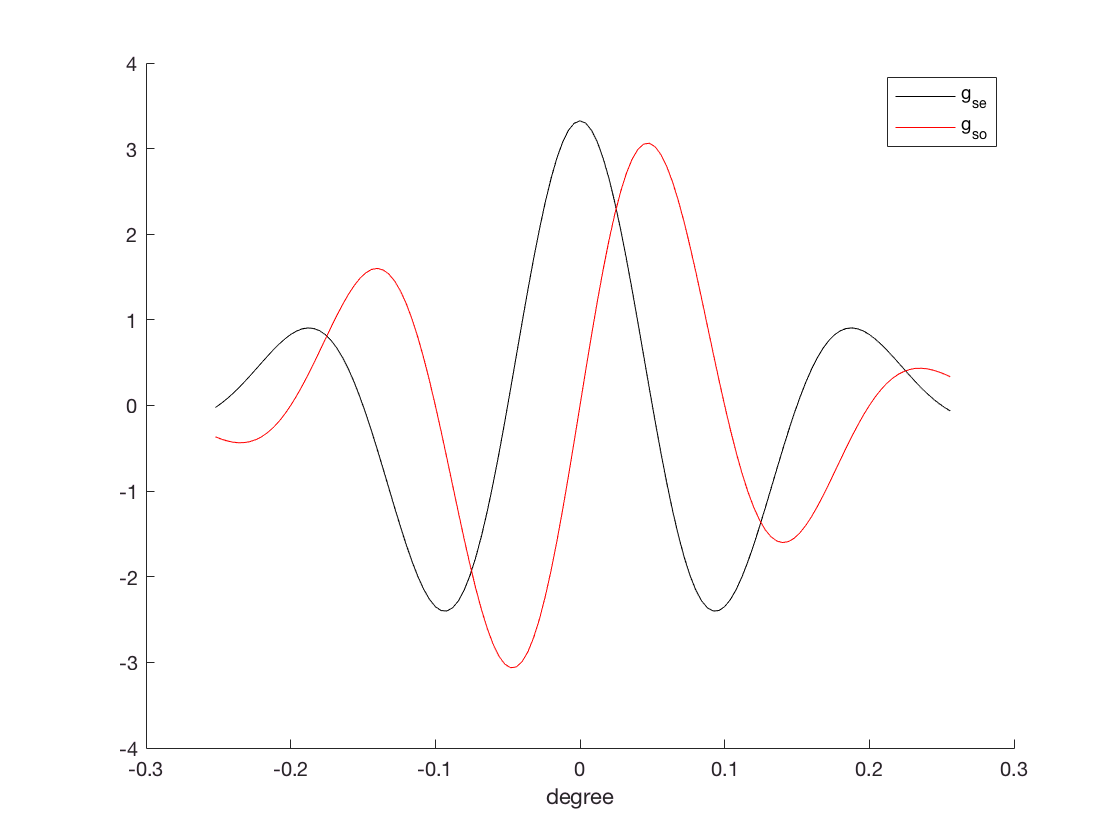

alpha = 100; beta = 0.9;
n1 = 6; n2 = 9;
k = 120; %s^-1
kx = 5;
sx = 0.12;
dx = 0.004;
N = 128;
xstart = -(N/2-1)*dx;
xend = N/2*dx;
x = xstart:dx:xend;
gse = 1/(sqrt(2*pi)*sx)*exp(-x.^2/(2*sx^2)).*cos(2*pi*kx*x);
gso = 1/(sqrt(2*pi)*sx)*exp(-x.^2/(2*sx^2)).*sin(2*pi*kx*x);
plot(x,gse,'k',x,gso,'r')
xlabel('degree')
legend('g_{se}','g_{so}', 'location','best')
box off

(2)

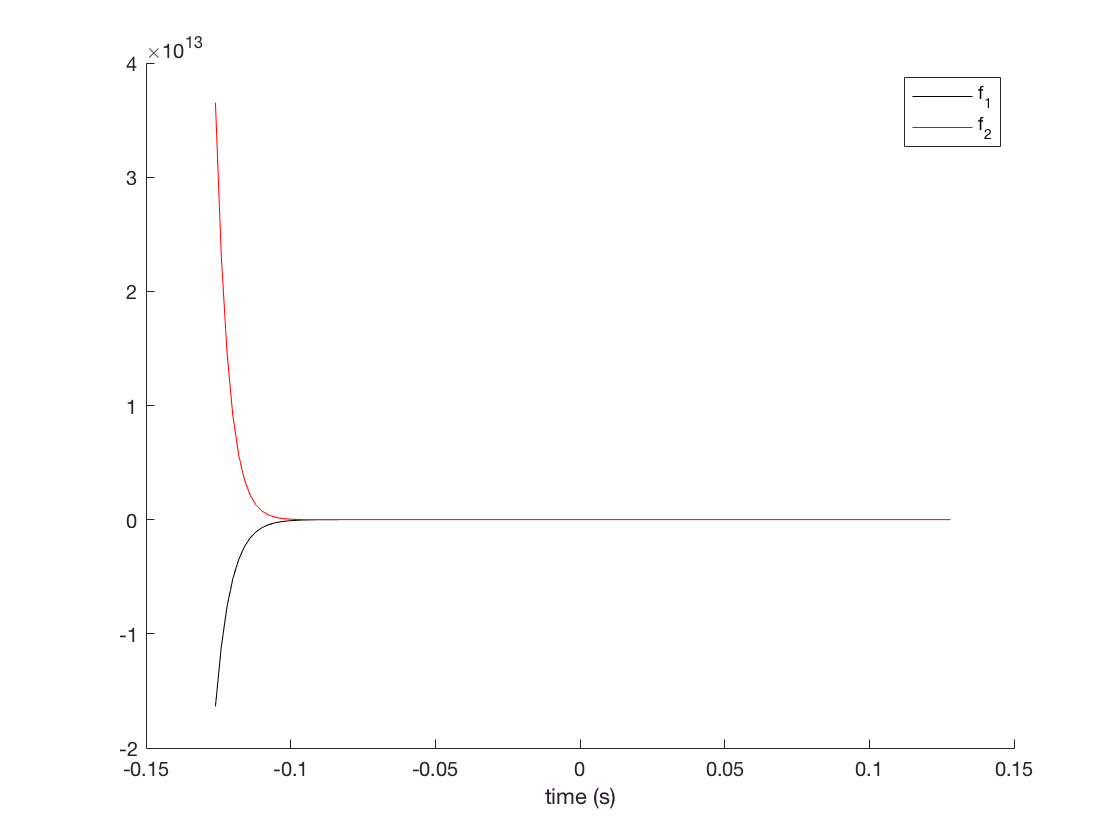

dt = 2*10^-3; %s
Tstart = -(N/2-1)*dt;
Tend = N/2*dt;
t = Tstart:dt:Tend;
f1 = alpha*(k*t).^n1.*exp(-k*t).*(1/factorial(n1) - beta*(k*t).^2/factorial(n1+2));
f2 = alpha*(k*t).^n2.*exp(-k*t).*(1/factorial(n2) - beta*(k*t).^2/factorial(n2+2));
plot(t,f1,'k',t,f2,'r')
xlabel('time (s)')
legend('f_1','f_2','location','best')
box off

(3)

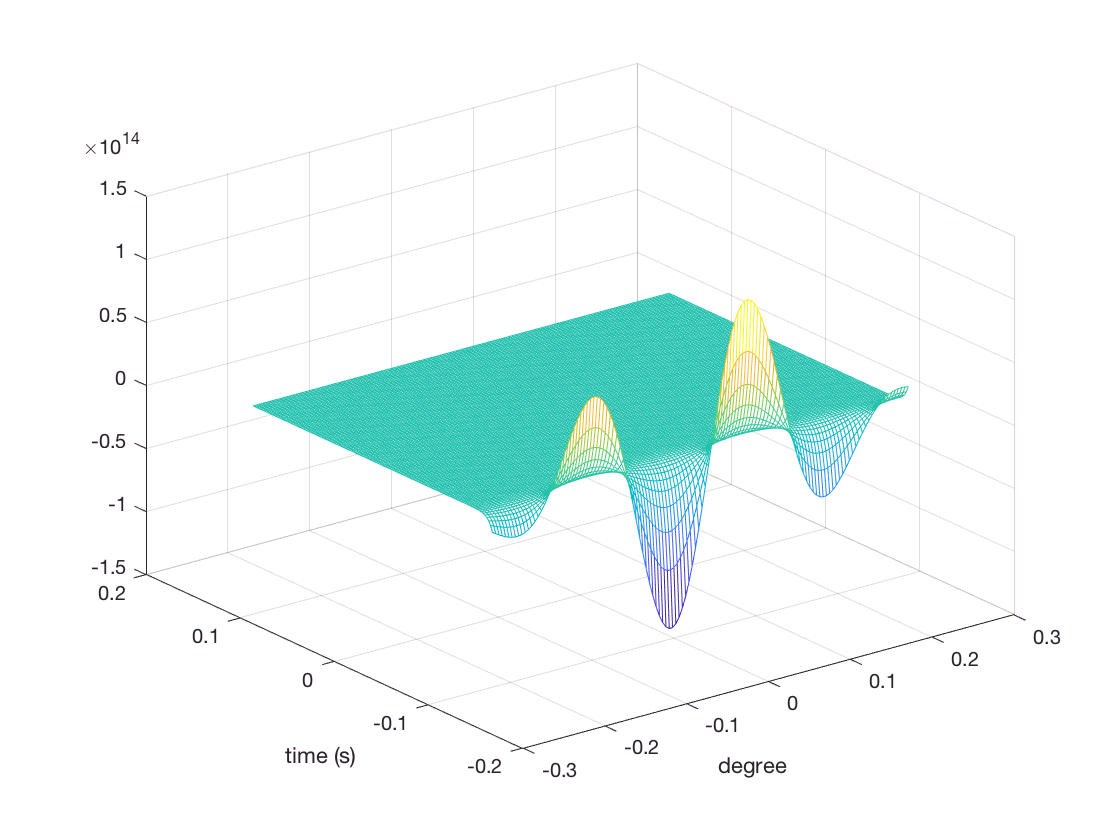

g = gse.*f1'+gso.*f2';
mesh(x,t,g)
ylabel('time (s)')
xlabel('degree')

(4)

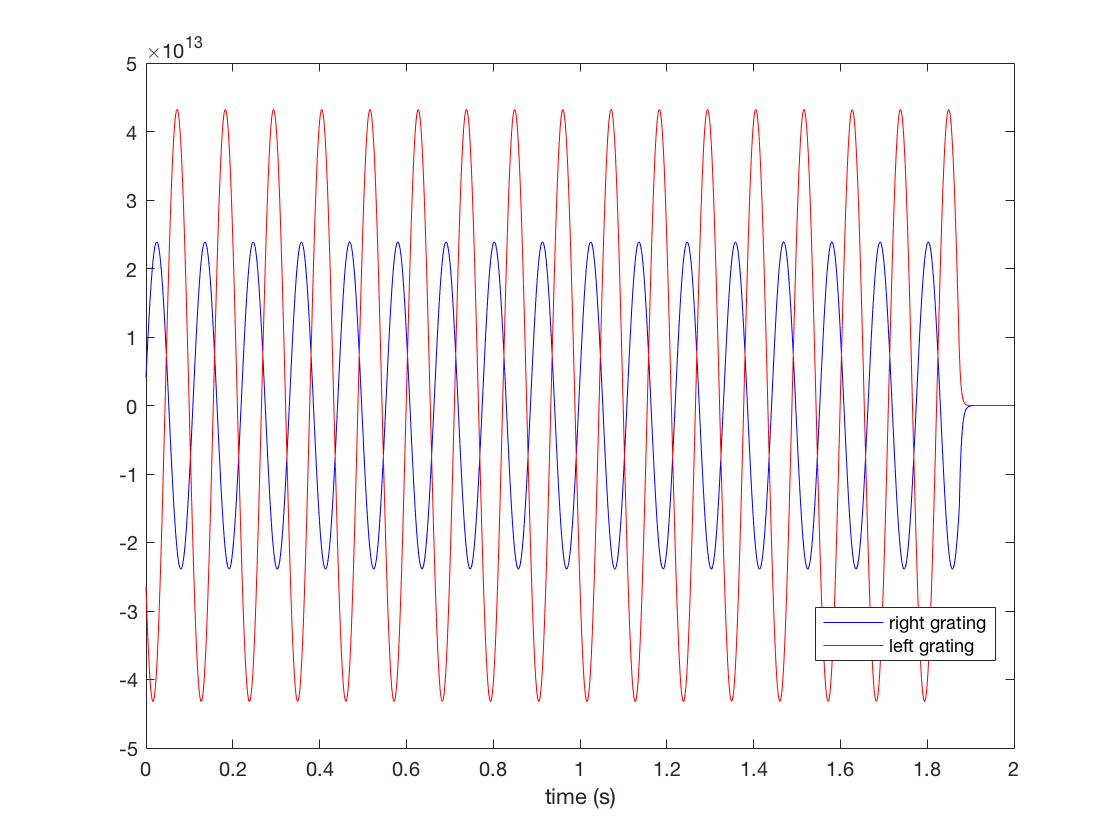

nx = 4.5;
nt = 9;
T0 = 2;
T = (0:dt:T0)';
gr = cos(2*pi*(nx*repmat(x,[length(T) 1]) - nt*repmat(T,[1,N])));
gr_e_s = gr*gse';
con = conv(gr_e_s,f1);
gr_e_st = con(64:64+length(T)-1)*dt;
gl = cos(2*pi*(nx*repmat(x,[length(T) 1]) + nt*repmat(T,[1,N])));
gl_e_s = gl*gse';
con = conv(gl_e_s,f1);
gl_e_st = con(64:64+length(T)-1)*dt;
gr_o_s = gr*gso';
con = conv(gr_o_s,f2);
gr_o_st = con(64:64+length(T)-1)*dt;
gl_o_s = gl*gso';
con = conv(gl_o_s,f2);
gl_o_st = con(64:64+length(T)-1)*dt;
g_r = gr_e_st+gr_o_st;
g_l = gl_o_st+gl_o_st;
plot(T,g_r,'b',T,g_l,'r')
legend('right grating','left grating', 'location', 'best')
xlabel('time (s)')

4. Signal detection based on Gaussian distributed spike numbers

(1)

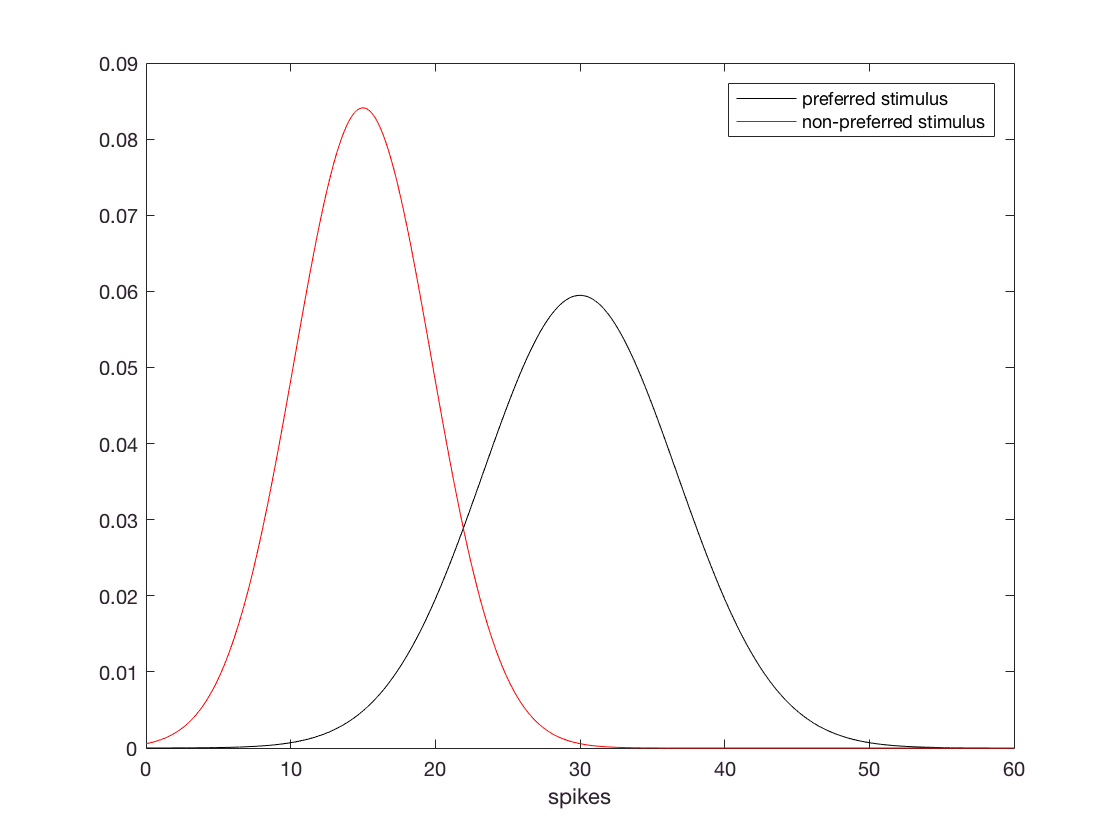

m = [30 15];
s2 = 1.5*m;
s = sqrt(s2);
x = 0:0.01:60;
pp = normpdf(x,m(1),s(1));
pn = normpdf(x,m(2),s(2));
plot(x,pp,'k',x,pn,'r')
xlabel('spikes')
legend('preferred stimulus','non-preferred stimulus')

(2)

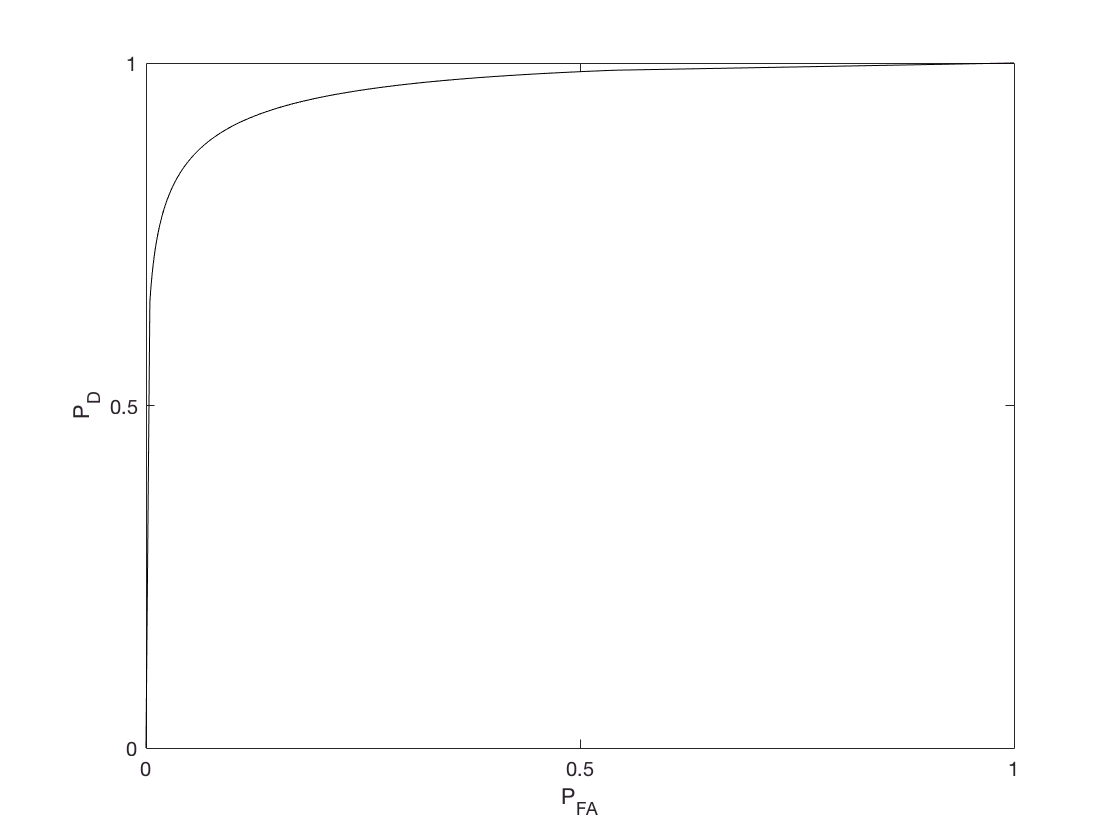

mu = (m(1)-m(2))/s(2);
sigma = s(1)/s(2);
rho_0 = 2*sigma^2*log(sigma);
l_val_vect = -3:0.05:3;
for j = 1:length(l_val_vect)
        l_val = l_val_vect(j);
        rho = rho_0 + 2*sigma^2*l_val;

        d_2 = sigma^2*(mu^2+rho)-rho;
    
        if ( d_2 > 0 )
            d = sqrt(sigma^2*(mu^2+rho)-rho);

            y_p = (-mu + d)/(sigma^2-1);
            y_m = (-mu - d)/(sigma^2-1);

            pfa(j) = normcdf(y_m,0,1) + (1-normcdf(y_p,0,1));
            pd(j) = normcdf(y_m,mu,sigma) + (1-normcdf(y_p,mu,sigma));
        end
end
inds1 = find(~isnan(pfa));
inds2 = find(~isnan(pd));
[p_fa, ix] = sort(pfa(inds1));
p_fa = [0 p_fa 1];
p_d = pd(inds1(ix));
p_d = [0 p_d 1];
plot(p_fa,p_d,'k');
xlabel('P_{FA}')
ylabel('P_D')
xlim([0 1])
ylim([0 1])
xticks([0 0.5 1])
yticks([0 0.5 1])

(3)

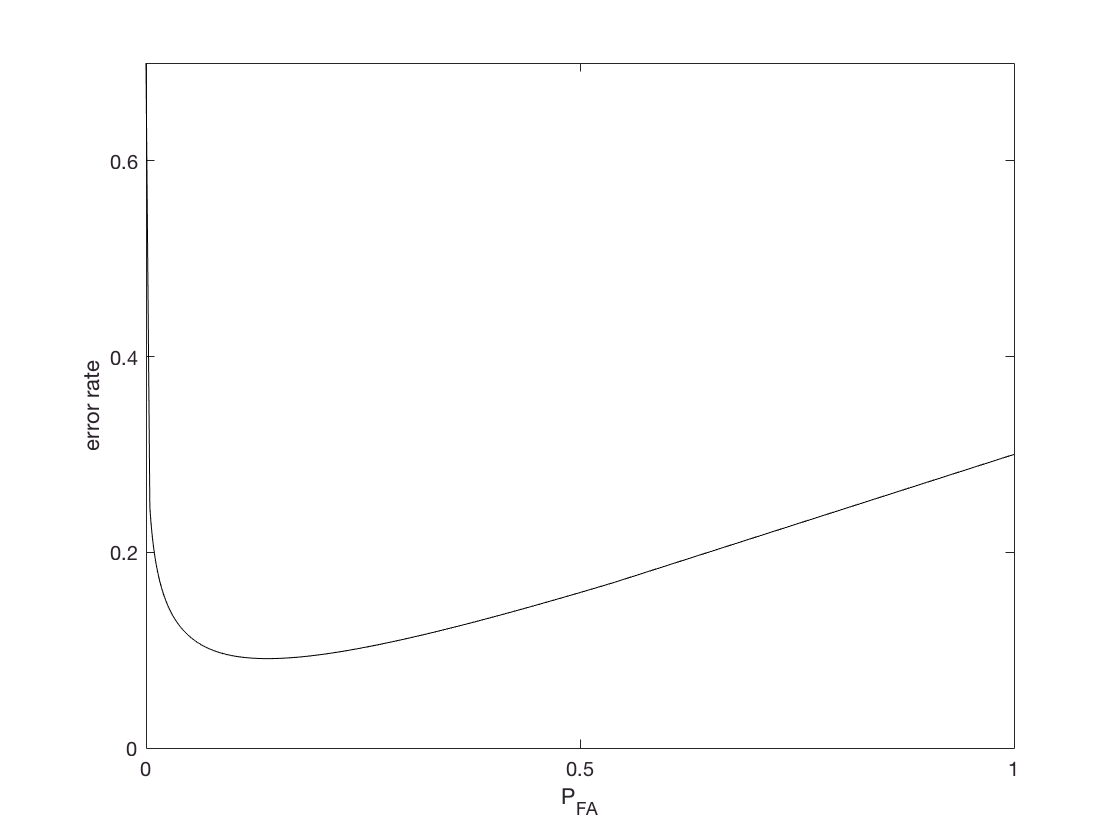

error = 0.3*p_fa + 0.7*(1-p_d);
plot(p_fa,error,'k')
xlabel('P_{FA}')
ylabel('error rate')
xticks([0 0.5 1])
yticks([0:0.2:0.8])

min_error = min(error);
min_pfa = pfa(find(error == min_error));
x = sprintf('The minumum error rate is %f. and the corresponding fals-alarm rate is %f.',min_error,min_pfa);
display(x)

x = 'The minumum error rate is 0.091342. and the corresponding fals-alarm rate is 0.033153.'

(4)

area = trapz(p_fa,p_d);
x = sprintf('The area under the ROC curve is %f.',area);
display(x)

x = 'The area under the ROC curve is 0.964244.'

Because the maximum area under ROC curve is 1, the performance of this single neuron is excellent. (The possiblity of this neuron to make correct decision is significant.).

 (5) The decision rule of (2) is optimal to characterize this single neuron but may not optimal to represent the animal behavior. The animals performance can be obtained by pooling information across multiple neurons. The performance will be determined by the correlation among the pool of neurons.

Appendix: Functions used for question 1.

function [t,v1] = mid1(syn)
l = 0.1; %cm, cable length
a = 1*10^-4; %cm, canle radius 
Cm = 1; %µF/cm^2
T = 10; %ms
gCl = 1/15; %mS/cm^2
Ra = 0.3; %kOhm cm
dx = 1*10^-4; %cm
dt = 0.05;  
tau = Cm/gCl;
tau_alpha = 1/2; %ms
lambda = sqrt(a/(2*Ra*gCl));
N_x = l/dx;
A = 2*pi*a*dx;
x = dx/2:dx:l-dx/2;
N_t = T/dt;
v = zeros(N_x,1);
e = ones(N_x,1);
S = spdiags([-e 2*e -e], -1:1, N_x, N_x)/dx/dx;
S(1,1) = 1/dx/dx;
S(N_x,N_x) = 1/dx/dx;
B = dt/2*(lambda^2*S+speye(N_x))/tau;
B = speye(N_x)+B;
c = round(syn.loc/dx);
d = (c-1)*(N_x+1)+1;
Ba= B(d);
I = syn.gsyn*(dt/2)/Cm/A;
v1 = zeros(length(syn.loc),N_t);
t = 0;
c0 = I.*((t-syn.t1)./tau_alpha).*exp(1-(t-syn.t1)./tau_alpha).*(t>syn.t1);
t = dt;
c1 = I.*((t-syn.t1)./tau_alpha).*exp(1-(t-syn.t1)./tau_alpha).*(t>syn.t1);
r = zeros(N_x,1);
r(c) = syn.vsyn*(c0 + c1)';


for j=2:N_t
    
    B(d) = Ba+c1;
    v = B\r;
    v1(:,j) = v(c);

    t = j*dt;

    c0 = c1;
    c1 = I.*((t-syn.t1)./tau_alpha).*exp(1-(t-syn.t1)./tau_alpha).*(t>syn.t1);
    r = 2*v - r;
    r(c) = r(c) + syn.vsyn*(c0 + c1)';

end
t = linspace(0,T,N_t);

end

function prt(t,v1)
plot(t,v1(1,:),'k',t,v1(2,:),'r')
box off
xlabel('t (ms)')
ylabel('v (mV)')
xticks([0 1 2 3 4 5 6 7 8 9 10])
legend('inhibitory','excitatory','location', 'best')
peak1 = min(v1(1,:));
loc1 = find(v1(1,:) == peak1);
peak2 = max(v1(2,:));
loc2 = find(v1(2,:) == peak2);
ploc = [loc1 loc2];
tp = t(ploc);
X = sprintf('For inhibitory, the peak value is %f mV, the time of peak is at %f ms.',peak1,tp(1));
Y = sprintf('For excitatory, the peak value is %f mV, the time of peak is at %f ms.',peak2,tp(2));
display(X)
display(Y)
end